# PubChem_Similarity

Search for chemical structures in PubChem via a Fingerprint Tanimoto Similarity Search

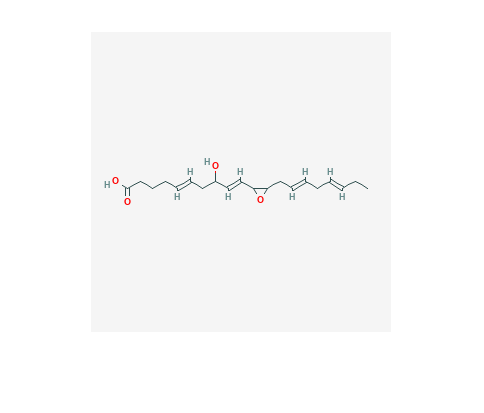

% Vincent F. Scalfani, Serena C. Ralph, and Jason E. Bara 
% The University of Alabama
% Version: 1.0, created with MATLAB R2018a

% Define PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';

% Retrieve and display PNG Image of Hepoxilin A4; CID = 6438949
CID_SS_query = '6438949';

CID_url = [api 'cid/' CID_SS_query '/PNG'];
[CID_img,map] = imread(CID_url);
imshow(CID_img,map)

% set MATLAB web options to a 30 second timeout
options = weboptions('Timeout', 30);

## Retrieve InChI and SMILES

% Retrieve InChI
inchi_url = [api 'cid/' CID_SS_query '/property/inchi/TXT'];
inchi = webread(inchi_url, options);
disp(inchi)

InChI=1S/C20H30O4/c1-2-3-4-5-6-10-13-18-19(24-18)16-15-17(21)12-9-7-8-11-14-20(22)23/h3-4,6-7,9-10,15-19,21H,2,5,8,11-14H2,1H3,(H,22,23)/b4-3+,9-7+,10-6+,16-15+



% Retrieve Isomeric SMILES
IS_url = [api 'cid/' CID_SS_query '/property/IsomericSMILES/TXT'];
IS = webread(IS_url, options);
disp(IS)

CC/C=C/C/C=C/CC1C(O1)/C=C/C(C/C=C/CCCC(=O)O)O



## Perform a Similarity Search

% Search for chemical structures by Similarity Search (SS), 
% (2D Tanimoto threshold 95% to Hepoxilin A4; CID = 6438949)
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
SS_url = [api 'fastsimilarity_2d/cid/' CID_SS_query '/cids/JSON?Threshold=95'];
SS_CIDs = webread(SS_url,options);
SS_CIDs = num2cell(SS_CIDs.IdentifierList.CID)

SS_CIDs = 33×1 cell array
    {[  5460414]}
    {[  5283211]}
    {[ 52921899]}
    {[  5280743]}
    {[ 90476806]}
    {[ 16760501]}
    {[  6438949]}
    {[  5353666]}
    {[     3586]}
    {[121225549]}
    {[ 71728442]}
    {[ 71728419]}
    {[ 71728401]}
    {[ 60060307]}
    {[ 44237273]}
    {[ 23639334]}
    {[ 21158465]}
    {[ 14522145]}
    {[  5283207]}
    {[  3246905]}
    {[ 90990554]}
    {[ 14333594]}
    {[  9997168]}
    {[ 10336997]}
    {[ 10359542]}
    {[ 10714074]}
    {[ 14333593]}
    {[100982635]}
    {[100982651]}
    {[101617712]}
    {[101617713]}
    {[124303601]}
    {[124674189]}


% set a CID limit to 100 max (can be higher, but useful for initial testing)
number_SS_CIDs = length(SS_CIDs)

number_SS_CIDs = 33

if number_SS_CIDs > 100
        
        SS_CIDs = SS_CIDs(1:100)      
else
    disp('Number of SS_CIDs not changed')    
end

Number of SS_CIDs not changed


## Retrieve Identifier and Property Data

% Create an identifier/property dataset from Similarity Search results
% Retrieve the following data from CID hit results:
% InChI, Isomeric SMILES, MW, HBond Donor Count, HBond Acceptor Count, XLogP

for r = 1:length(SS_CIDs)
    CID = SS_CIDs{r};
    
    % define api calls
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_InChI_url = [api 'cid/' num2str(CID) '/property/InChI/TXT'];
    CID_IsoSMI_url = [api 'cid/' num2str(CID) '/property/IsomericSMILES/TXT'];
    CID_MW_url = [api 'cid/' num2str(CID) '/property/MolecularWeight/TXT'];  
    CID_HBond_D_url = [api 'cid/' num2str(CID) '/property/HBondDonorCount/TXT'];
    CID_HBond_A_url = [api 'cid/' num2str(CID) '/property/HBondAcceptorCount/TXT'];
    CID_XLogP_url = [api 'cid/' num2str(CID) '/property/XLogP/TXT'];
        
    % retrieve identifer and property data
    try
        CID_InChI = webread(CID_InChI_url,options);      
    catch ME
        CID_InChI = 'not found'
    end
        % be polite to PubChem server
        n = 0.5;
        pause(n)
     
    try
        CID_IsoSMI = webread(CID_IsoSMI_url,options);     
    catch ME  
        CID_IsoSMI = 'not found'
    end
        n = 0.5;
        pause(n)
    
    try
        CID_MW = webread(CID_MW_url,options);
    catch ME
        CID_MW = 'not found'
    end    
        n = 0.5;
        pause(n)
            
    try
        CID_HBond_D = webread(CID_HBond_D_url,options);
    catch ME
        CID_HBond_D = 'not found'
    end
        n = 0.5;
        pause(n)
        
    try
        CID_HBond_A = webread(CID_HBond_A_url,options);
    catch ME
        CID_HBond_A = 'not found'
    end
        n = 0.5;
        pause(n)
       
    try
        CID_XLogP = webread(CID_XLogP_url,options);
    catch ME
        CID_XLogP = 'not found'
    end
        n = 0.5;
        pause(n)
        
      % add property data to SS_CIDs data array 
        SS_CIDs{r,2} = CID_InChI;
        SS_CIDs{r,3} = CID_IsoSMI;
        SS_CIDs{r,4} = CID_MW;
        SS_CIDs{r,5} = CID_HBond_D;
        SS_CIDs{r,6} = CID_HBond_A;
        SS_CIDs{r,7} = CID_XLogP;
                                       
end


## Compile Data into a Table

% convert cell array to string and remove leading and trailing white space
SS_CIDs_string = strtrim(string(SS_CIDs));

% convert to table
SSq_table = array2table(SS_CIDs_string, 'VariableNames',{'CID', 'InChI','IsoSMI','MW',...
    'HBond_D','HBond_A','XLogP'})

SSq_table = 33×7 table
        CID                                                                                             InChI                                                                                                                     IsoSMI                                     MW         HBond_D    HBond_A    XLogP
    ___________    ________________________________________________________________________________________________________________________________________________________________________________    _____________________________________________________________    ____________    _______    _______    _____

    "5460414"      "InChI=1S/C20H32O4/c1-2-3-4-5-6-10-13-18-19(24-18)16-15-17(21)12-9-7-8-11-14-20(22)23/h6-7,9-10,15-19,2

% rearrange table so that Isomeric SMILES are in column 1
SSq_table2 = SSq_table(:, {'IsoSMI' 'CID' 'InChI' 'MW' 'HBond_D' 'HBond_A' 'XLogP'})

SSq_table2 = 33×7 table
                               IsoSMI                                    CID                                                                                             InChI                                                                                               MW         HBond_D    HBond_A    XLogP
    _____________________________________________________________    ___________    ________________________________________________________________________________________________________________________________________________________________________________    ____________    _______    _______    _____

    "CCCCC/C=C\C[C@H]1[C@H](O1)/C=C/C(C/C=C\CCCC(=O)O)O"             "5460414"      "InChI=1S/C20H32O4/c1-2-3-4-5-6-10-13

% data export as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;

% change directory to selected folder
cd(save_folder)

writetable(SSq_table2,'MATLAB_Similarityq_results.txt','Delimiter','tab')

## Retrieve Images of CID Compounds from Similarity Search

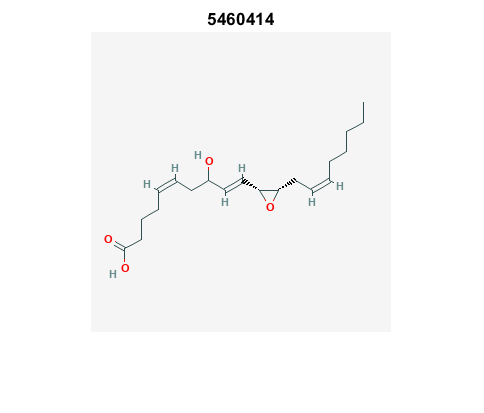

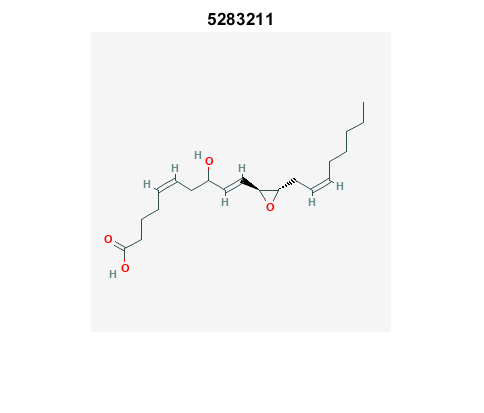

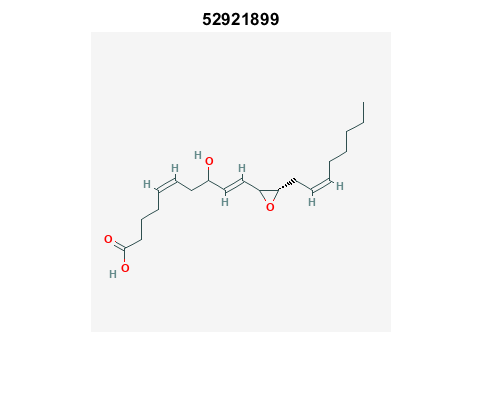

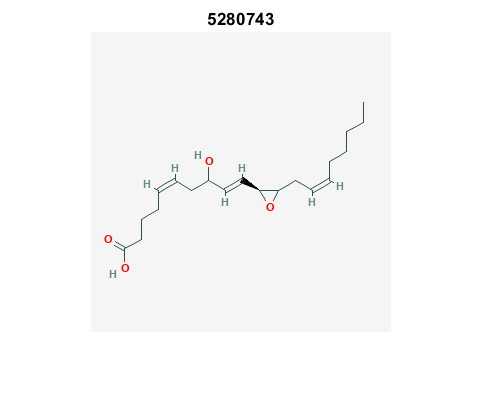

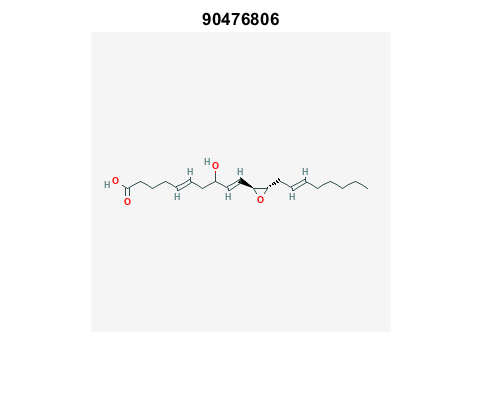

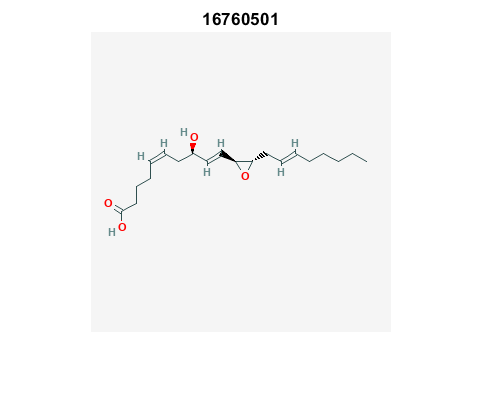

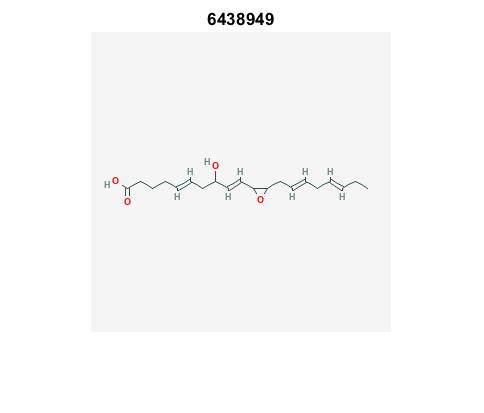

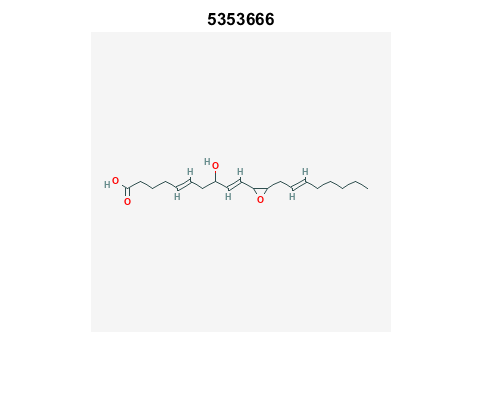

% loop through hit CIDs and show images
for r = 1:length(SS_CIDs)
    CID = SS_CIDs{r};
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_url = [api 'cid/' num2str(CID) '/PNG'];
    
    try
        % retrieve CID PNG image and display
        [CID_img,map] = imread(CID_url);
        figure;
        imshow(CID_img,map)
        drawnow;
        title(num2str(CID));
        
        % be polite to PubChem server
        n = 0.5;
        pause(n);
        
    catch
        disp('CID image not found')
        disp('Execution will continue')
    end
    
end